Keanu Francis

Z#23456741  

Assignment 2 - Imagle Labeler

## Loading Unlabled Data

From the Documentation i loaded the books dataset and added labes for the book the title and author. Though this was not done for every book 

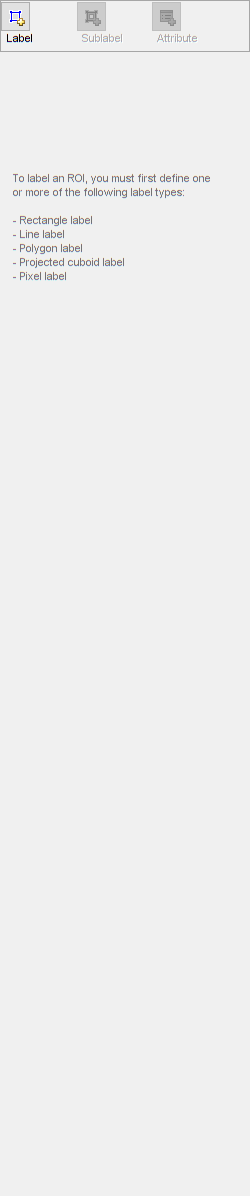

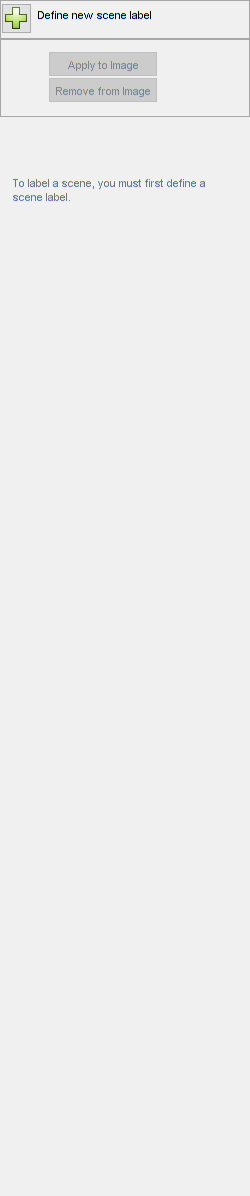

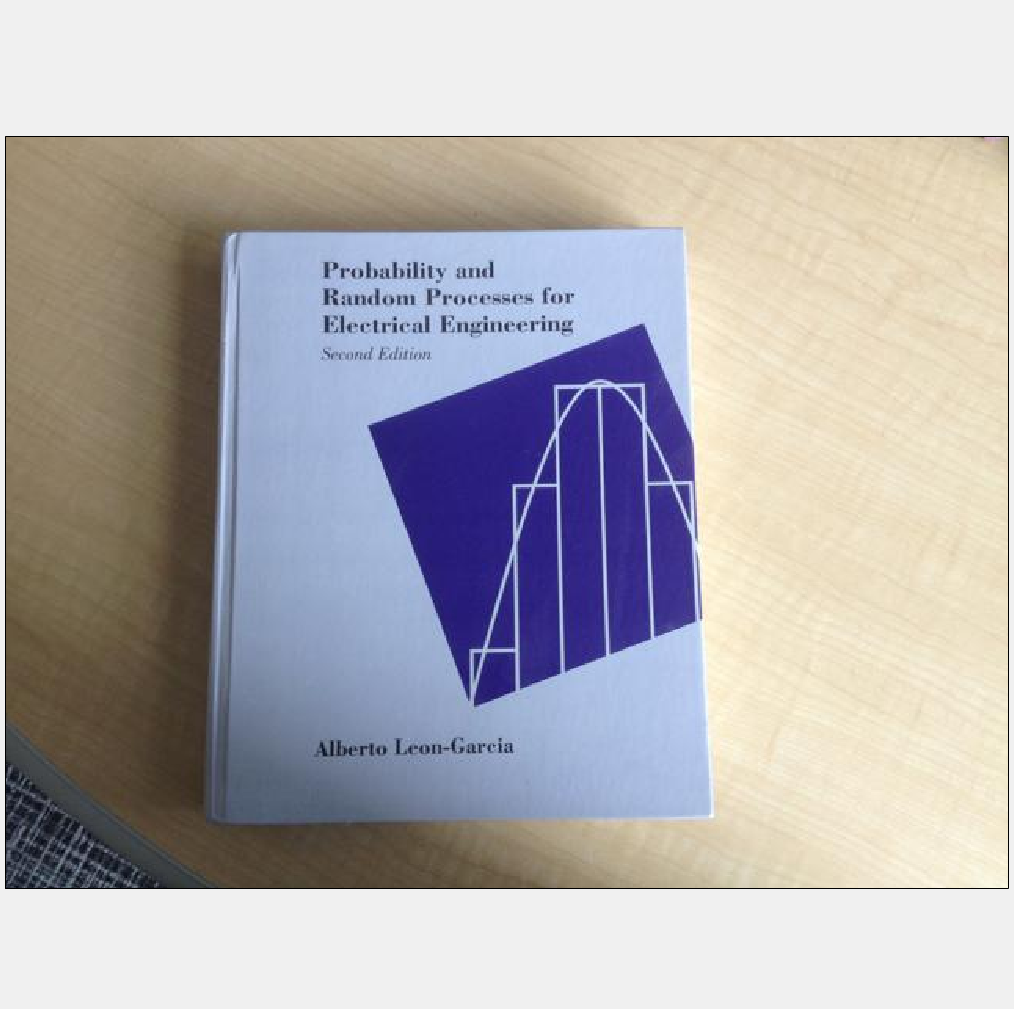

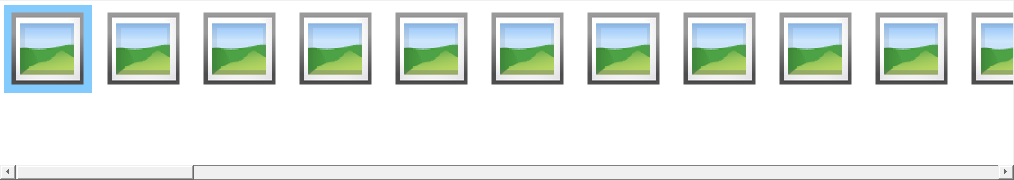

imageFolder = fullfile(toolboxdir('vision'),'visiondata','bookcovers');
imds = imageDatastore(imageFolder);
imageLabeler(imds);

### Loading book gtruth 

The gtruth file can either be saved in the workspace or as a file in this case we will save it as a file called 'gtruthBooks.mat' and load it into the workspace

gtruthBooks = load("gtruthBooks.mat")

gtruthBooks = struct with fields:
    gTruth: [1×1 groundTruth]


gtruthBooks=gtruthBooks.gTruth

gtruthBooks =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×6 table]
           LabelData: [58×1 table]


gtruthBooks.DataSource

ans = groundTruthDataSource for an image collection with properties

                      Source: {
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book1.jpg';
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book10.jpg';
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book11.jpg'
                               ... and 55 more
                              }

gtruthBooks.LabelDefinitions

ans = 1×6 table
      Name         Type               LabelColor             Group      Description    Hierarchy 
    _________    _________    __________________________    ________    ___________    __________

    {'Books'}    Rectangle    0.5862    0.8276    0.3103    {'None'}    {0×0 char}     1×1 struct


## Loading our Own data

Would like to perform a similar operation with the labeling of faces.

in this case we will use the data set provided from kaggle this time we will labeling only the mouth then using these labels to train an object detection algorythm.

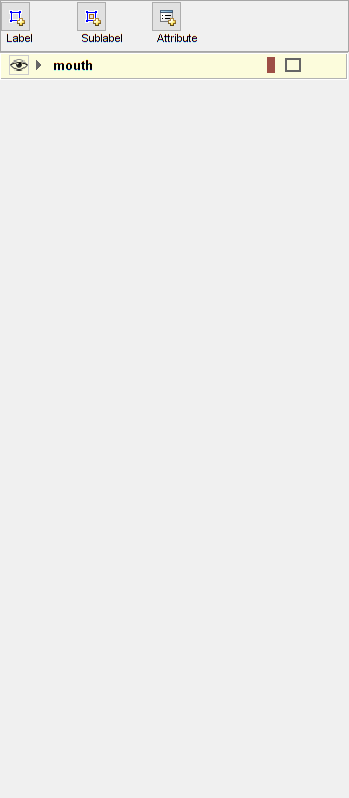

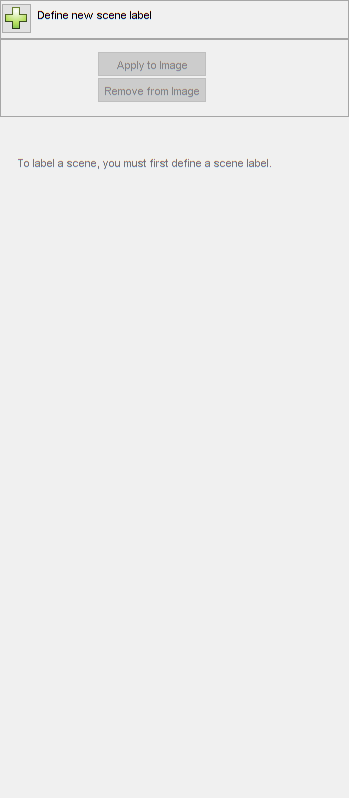

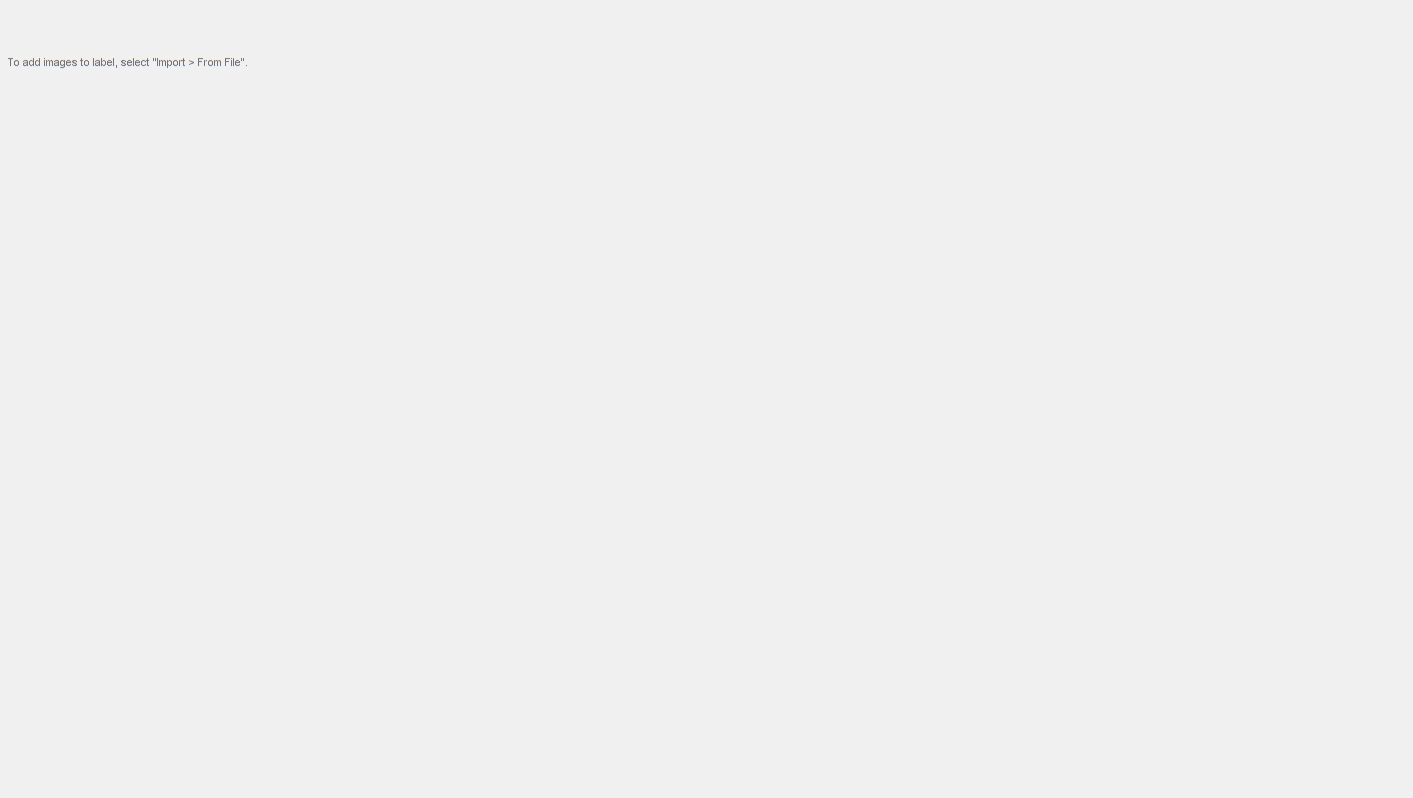

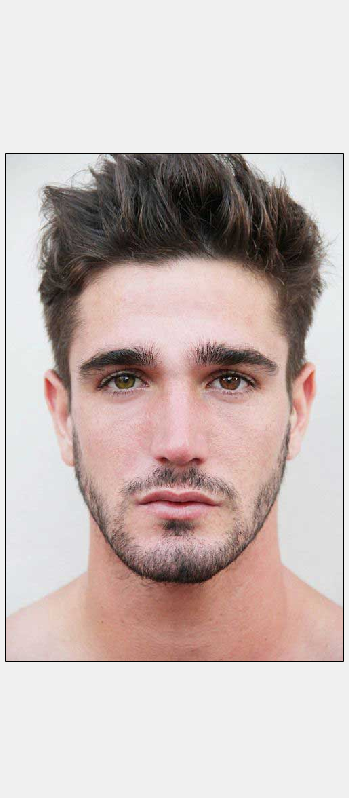

fData=imageDatastore("Faces");
imageLabeler(fData);

## Gtruth data

After saving the data to a file we can the review the information

load("mouthgtruth.mat")
gTruth.LabelDefinitions

ans = 1×1 cell array
    {0×0 char}


## Training detector

Next we can train the trainACFObjectDetector using these images and labels

mouthGtruth= selectLabelsByName(gTruth,'mouth');
traininData= objectDetectorTrainingData(mouthGtruth);
detector=trainACFObjectDetector(traininData,'NumStages',5);

ACF Object Detector Training
The training will take 5 stages. The model size is 20x43.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 65 positive examples and 325 negative examples...Completed.
The trained classifier has 76 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 325 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 65 positive examples and 325 negative examples...Completed.
The trained classifier has 248 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 325 new negative examples for training.
Compute aggregated channel features...Com

save('Detector.mat','detector');

## Testing Detecter

we can now test the train the detecter to see if it can correctly identify mouths of other images we can use a picture from the test data file. bboxes will contain the coordinates for the bounding boxes and score will contain the confidence score for each box.

load("Detector.mat")
img=imread("TestData\1 (305).jpg");
[bboxes,scores]=detect(detector,img)

bboxes =    154   270   323   150


scores = 66.8546

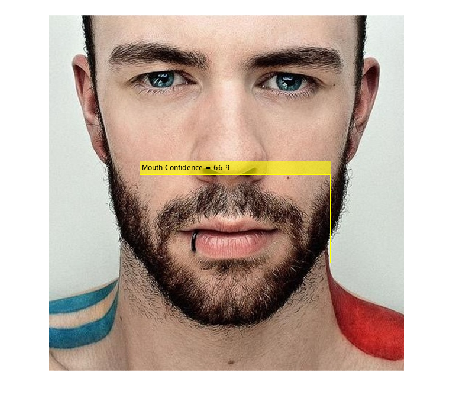

for i = 1:length(scores)
   annotation = sprintf('Mouth Confidence = %.1f',scores(i));
   img = insertObjectAnnotation(img,'rectangle',bboxes(i,:),annotation);
end

imshow(img)